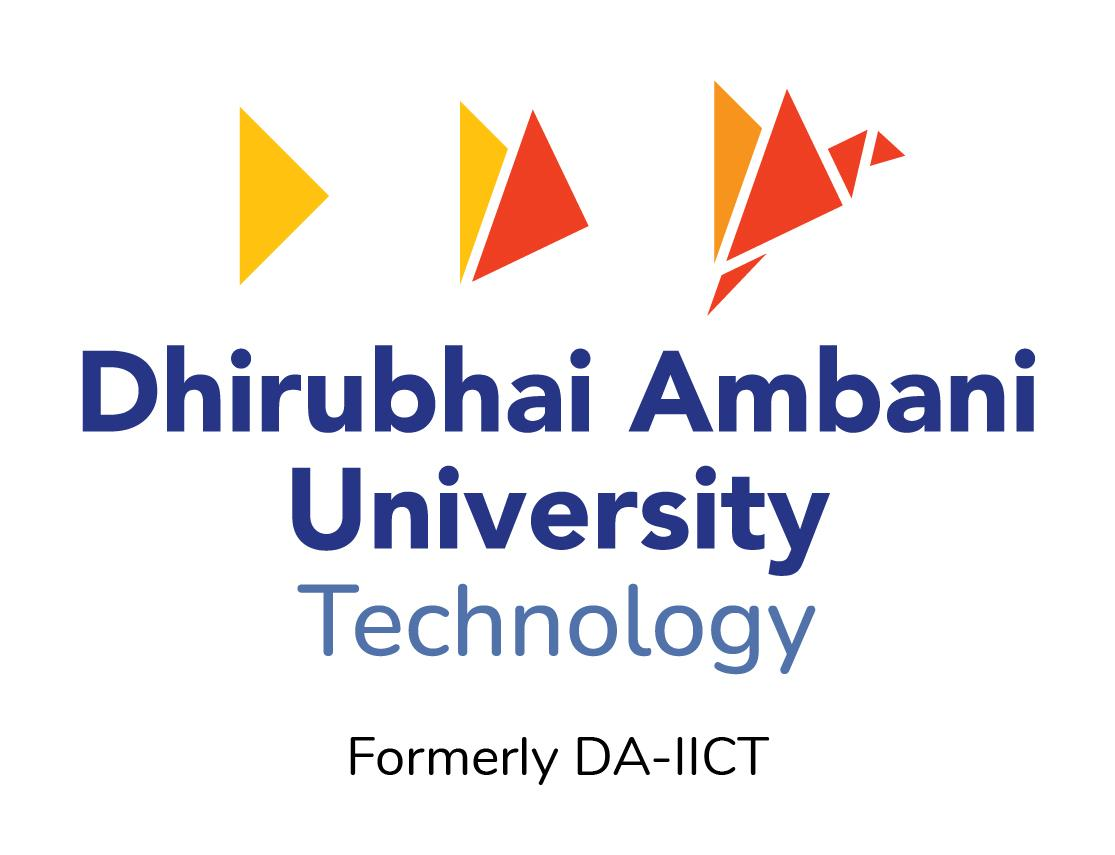

# CT216: Introduction to Communication Systems

# Lab 2 (Experiments): Definition of Information and Information Transfer over a Communication Channel

The computer simulation based experiments in the Lab ask you to perform experiments to obtain understanding how much information can be transmitted reliably (i.e., without errors) even when the channel over which the information is transmitted is noisy. One of the main purposes of this Lab is for you to experiment with the values of $q$ and $p$ parameters of the C-disease problem, i.e., the BSC($p$) channel, and observe and plot the resulting entropies numerically and graphically. 

You are asked to perform the experiments using the following code (extra credits if you think of and devise new experiments and develop the Matlab/Python code). Show the results and make your observational/insightful comments regarding these results.

# A Model of Causes and Their Influence on the Effects

In this exercise we will consider the binary case, i.e., the cause is binary and the observed effect is also binary

### Step 1: Define a Bernouilli Source

Define the Bernouilli($q$) source X and calculate its entropy. 

q =0.1;
pX = [q 1-q];
H_X = entropy_function(pX)

H_X = 0.4690

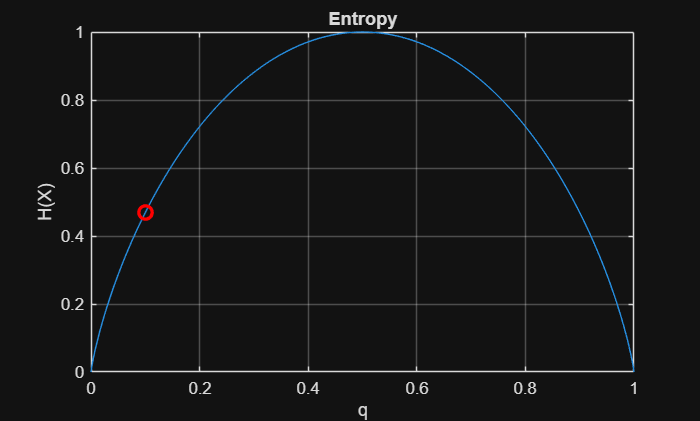

q_current = q;  
   H_current = entropy_function([q_current 1-q_current]);

function H = entropy_function(p)
    p = p(p > 0);          % Remove zero probabilities
    H = -sum(p .* log2(p));
    end
    q_vec = linspace(0,1,1000);      % q values from 0 to 1
H = zeros(size(q_vec)); 

for i = 1:length(q_vec)
    pX_temp = [q_vec(i) 1-q_vec(i)];
    H(i) = entropy_function(pX_temp);
end

plot(q_vec,H)
hold on
plot(q_current, H_current, 'ro', 'MarkerSize',8, 'LineWidth',2) % current value 0f H(x) and q
hold off

xlabel('q')
ylabel('H(X)')
title('Entropy')
grid on

### Step 2: Define a the channel and its likelihood function

Define the likelihood function of the binary noisy channel. 

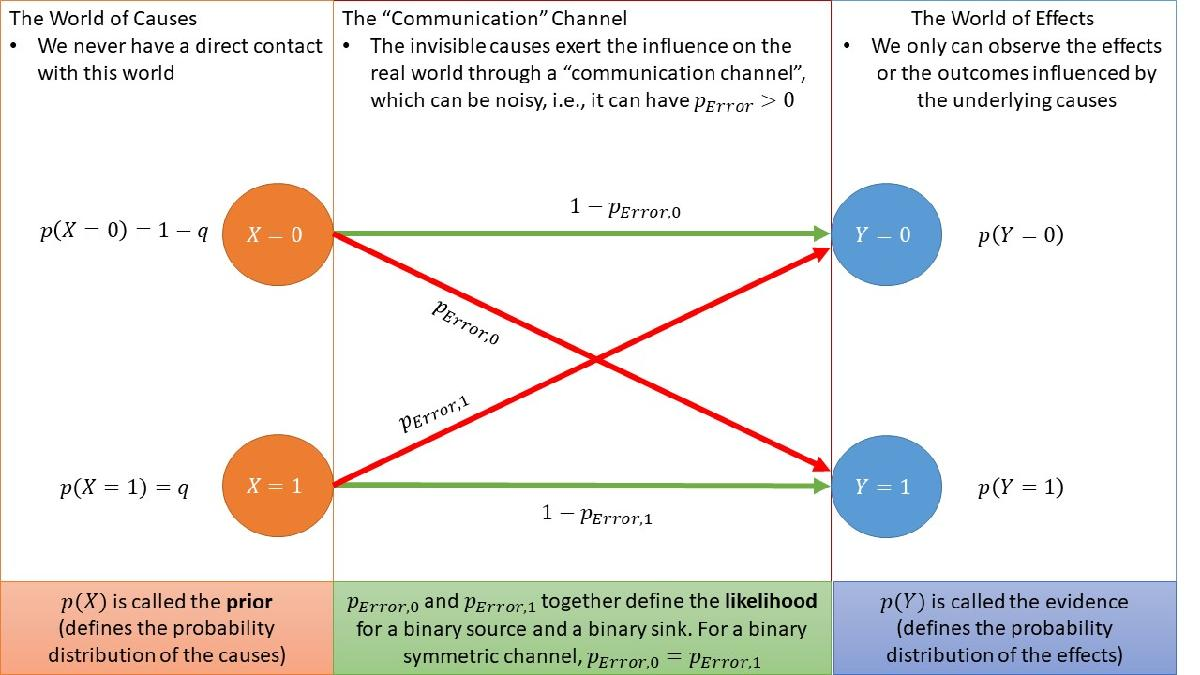

The first element of pYgivenX0 corresponds to $Y = 0$ and the second element corresponds to $Y = 1$, and likewise, the first element of pYgivenX1 corresponds to $Y = 0$ and the second element corresponds to $Y = 1$.

pError0 =0;
pYgivenX0 = [1-pError0 pError0]; % the likelihood function, i.e., the prob of [Y=0, Y = 1] when X = 0

pError1 =0;
pYgivenX1 = [pError1 1-pError1]; % the likelihood function [Y=0, Y = 1] when X = 1

### Step 3: Calculate the posterior on the source: the direct method

The (marginal) probability of the effect: i.e., the evidence or the probability $p(Y)$, is calculated using the rule of marginalization of the joint probability.

pY(1) = pYgivenX0(1)*pX(1)+pYgivenX1(1)*pX(2); % This is prob of Y = 0
pY(2) = pYgivenX0(2)*pX(1)+pYgivenX1(2)*pX(2); % This is prob of Y = 1

The posterior is calculated using the Bayes' rule:

pXgivenY0 = [pX(1)*pYgivenX0(1) pX(2)*pYgivenX1(1)]/pY(1)

pXgivenY0 =      1     0


pXgivenY1 = [pX(1)*pYgivenX0(2) pX(2)*pYgivenX1(2)]/pY(2)

pXgivenY1 =      0     1


### Step 4: Calculate the Conditional Entropy and the Information Transfer

The entropy of the RVs $\tilde{X}_n$ , where $n = 0$ or $1$, is called the conditional entropy (the entropy of $X$ conditioned on an observation $Y = n$). In today's quiz, you were asked to compare the conditional entropy $H(\tilde{X}_n)$ with the unconditional entropy $H(X)$. This topic of conditional entropy is explained on **Slides 67 onward of Lecture 2 slides posted on Google Classroom**. Please read these slides before experimenting with the following code. 

Note that $H(X)$ signifies the uncertainty at the receiver regarding the state $X = 0$ or $X = 1$ of the transmitter. The purpose of communication is to reduce this uncertainty at the receiver after observation of $Y$ (e.g., we say that we have received information only if the output of the communication channel reduces our uncertainty about the state of the transmitter. Can you think of some real-world real-life examples of this). However, $H(\tilde{X}_n)$ is the metric (a single scalar value) which succinctly captures the uncertainty at the receiver regarding $X$ after observation of $Y_n$. Using this argument, Shannon defined the information transfer over a noisy communication channel as the *difference* between the unconditional and the conditional entropies. The specific name is *Mutual Information *and it is defined as $I(X; Y) = H(X) - H(\tilde{X})$, where $H(\tilde{X})$ is the average of $H(\tilde X_n)$ over all values $Y = n$.

H_X

H_X = 0.0808

H_XgivenY0 = entropy_function(pXgivenY0)

H_XgivenY0 = 0

InformationTransfer_givenY0 = H_X - H_XgivenY0

InformationTransfer_givenY0 = 0.0808


H_X

H_X = 0.0808

H_XgivenY1 = entropy_function(pXgivenY1)

H_XgivenY1 = 0

InformationTransfer_givenY1 = H_X - H_XgivenY1

InformationTransfer_givenY1 = 0.0808


H_X

H_X = 0.0808

H_XgivenY = pY(1)*H_XgivenY0 + pY(2)*H_XgivenY1

H_XgivenY = 0

InformationTransfer = H_X - H_XgivenY

InformationTransfer = 0.0808

### Step 5: Evaluate the information transfer for varying values of $p_{Error} = p_{Error,0} = p_{Error,1}$

This step is similar to what we have done earlier for the Entropy function. There we varied $q$ parameter and evaluated the Entropy of the Information source for each value of $q$. The evaluated Entropy was plotted as a function of $q$.

In this section, we now repeat the same procedure, except the goal is to plot the information transfer capability of the BSC($p_{Error}$) in transferring the information generated by the Bernouilli($q$) source. This plot is obtained as a function of $p_{Error}$ for a specified $q$ value.

q =0.5;
pX = [1-q q];
H_X = entropy_function(pX)

H_X = 1

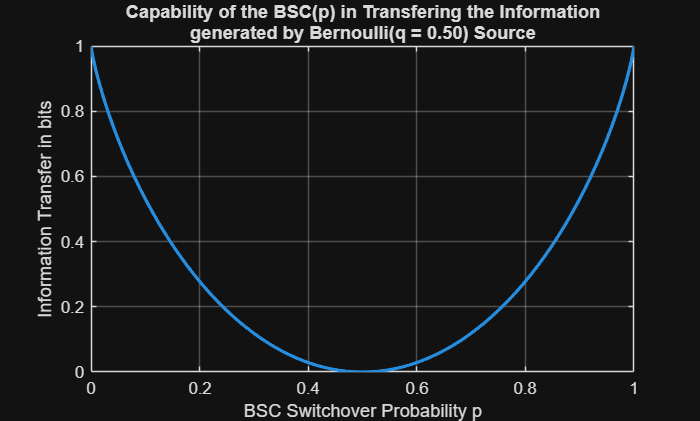


pErrorVec = 0:1e-3:1;
Info_X_Y = 0*pErrorVec;
kk = 0;
for pError = pErrorVec
    kk = kk+1;
    pYgivenX0 = [1-pError pError]; 
    pYgivenX1 = [pError 1-pError];
    pY(1) = pYgivenX0(1)*pX(1)+pYgivenX1(1)*pX(2);
    pY(2) = pYgivenX0(2)*pX(1)+pYgivenX1(2)*pX(2);
    pXgivenY0 = [pX(1)*pYgivenX0(1) pX(2)*pYgivenX1(1)]/pY(1);
    pXgivenY1 = [pX(1)*pYgivenX0(2) pX(2)*pYgivenX1(2)]/pY(2);
    H_X_givenY0 = entropy_function(pXgivenY0);
    H_X_givenY1 = entropy_function(pXgivenY1);
    H_X_givenY = pY(1)*H_X_givenY0 + pY(2)*H_X_givenY1;
    Info_X_Y(kk) = H_X - H_X_givenY;
end
plot(pErrorVec,Info_X_Y,linewidth=2)
xlabel('BSC Switchover Probability p'); ylabel('Information Transfer in bits')
title({'Capability of the BSC(p) in Transfering the Information',sprintf('generated by Bernoulli(q = %1.2f) Source',q)}); grid

LAB Report : 202401471 Lab02

In Step I,  I implemented the entropy function for a binary source and evaluated it for different values of the source probability ( q ). I plotted a graph of entropy versus ( q ) to study how uncertainty varies with the probability distribution of the source. From the graph, I observed that entropy reaches its maximum value when ( q = 0.5 ), which indicates that uncertainty is highest when both symbols are equally likely to occur. I also observed that entropy decreases as ( q ) approaches 0 or 1, showing that uncertainty reduces when one symbol becomes more likely than the other, also i have a red marker for the current H(X) and q which moves as we change the slider of q.

In Step II, sliding pError0 and pError1 controls how noisy the channel is, which directly affects uncertainty and information transfer between transmitter and receiver.

 Mutual Information Observations : 

- Mutual information was highest when the channel error probability was zero.

-  As error probability increased, mutual information decreased.

- When the channel became highly noisy, information transfer approached zero.